# DL draft

(Section 1/2/3)

github@hnxj; github@dynasim

## Initialization

clear;close all;clc;
PathToDynaSim = 'D:\Works\Computational'; % Change it based on your local path for dynasim 
cd(PathToDynaSim);
addpath(genpath('DynaSim'));
cd('DynaSim');

## 1.1: Baseline voltage optimization


$$:N \rightarrow f(r_v ; \nabla E_{leak})$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS1';

spec = dsCheckSpecification('HH');
vary = {'HH','Eleak',[-70 -60 -50 -40 -30]};
solver_options = {'tspan',[0 RunDuration],'solver','rk1','dt',.01,'compile_flag',0,'verbose_flag',1};
data = dsSimulate(spec,'vary',vary,solver_options{:});
dsPlot(data,'plot_type','waveform');

## Passing to DynaLearn

dl = DynaLearn(spec, study_dir, 'raw', 'HHNS1');
dl.dlSave();

## Load (ONLY IF ALREADY EXISTS)

id = 1; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial Eleak: %g\n', p.HH_ileak_Eleak);
target_RMP = -60;

% Define optimization parameters
dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = {['HH', '_V'], 1, [100 RunDuration], 'av'}; % 'av' is average voltage
dlTargetParameters = {{'MQE', 1, target_RMP, 1}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.3;
dlTrainOptions('dlTrainIncludeList') = ["_Eleak"];
dlTrainOptions('dlCheckpointCoefficient') = 1.1;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);
dl.dlSimulate();
dl.dlPlotAllPotentials('lfp');
fprintf("Initial membrane potential = %f", dl.dlLastOutputs{1});

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-1; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 10; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.5;
dlTrainOptions('dlTrainIncludeList') = ["_Eleak"];
dlTrainOptions('dlCheckpointCoefficient') = 1.5;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

dl.dlPlotBatchErrors(1);
dl.dlLoadOptimal();
dl.dlSimulate();
dl.dlPlotAllPotentials('lfp'); 
fprintf("Final membrane potential = %f", dl.dlLastOutputs{1});
optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final Eleak: %g\n', p.HH_ileak_Eleak);

## 1.2: Firing rate optimization


$$:N \rightarrow f(r_{fr} ; \nabla E_{leak}, I_{app})$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS2';

spec = dsCheckSpecification('HH');
vary = {'HH','Iapp',[-4 -1 0 1 4 7 8.80720 8.80721 8.80741 11 14 17]};
solver_options = {'tspan',[0 RunDuration],'solver','rk1','dt',.01,'compile_flag',0,'verbose_flag',1};
data = dsSimulate(spec,'vary',vary,solver_options{:});


PREPARING STUDY:

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\solve
Changing directory to D:\Works\Computational\DynaSim\solve
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\solve\solve_ode_20230830083145_614.m
Changing directory back to D:\Works\Computational\DynaSim

SIMULATING MODEL:
Solving system using D:\Works\Computational\DynaSim\solve\solve_ode_20230830083145_614.m
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\params.mat

Running simulation 1/12 (solver='rk1', dt=0.01, tspan=[0 500]) ...
Total Memory Used <= 1 GB 
Elapsed time: 0.1 seconds.
Changing directory to D:\Works\Computational\DynaSim\solve
Saving model parameters: D:\Works\Computational\DynaSim\solve\params.mat

Running simulation 2/12 (solver='rk1', dt=0.01, tspan=[0 500]) ...
Total Memory Used <= 1 GB 
Elapsed time: 0.0 seconds.
Changing directory to D:\Works\Computational\DynaSim\solve


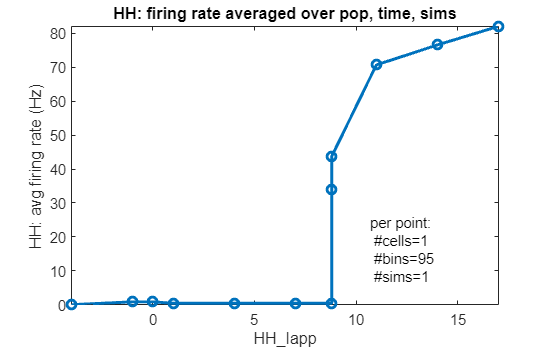

dsPlotFR(data);

## Passing to DynaLearn

dl = DynaLearn(spec, study_dir, 'raw', 'HHNS2');



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 0

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:

PREPARING SOLVER:
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS2\solve
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS2\solve\solve_ode_20230824134814_113.m
Changing directory back to D:\Works\Computational\DynaSim

SIMULATING MODEL:
Solving system using D:\Works\Computational\DynaSim\dlModels\HHNS2\solve\solve_ode_20230824134814_113.m
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS2\solve
Saving model parameters: D:\Works\Computational\DynaSim\dlModels\HHNS2\solve\params.mat

Running simulation 1/1 (solver='rk1', dt=0.01, tspan=[0 100]) ...
Total Memory Used <= 1 GB 
Elapsed time: 0.0 seconds.
Changing directory to D:\Works\Computational\DynaSim

Simul

dl.dlSave();


->Model saved in "dlModels/HHNS2/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 2; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS2 
Params.mat file loaded from dlModels/HHNS2 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial Iapp: %g, Eleak: %g\n', p.HH_Iapp, p.HH_ileak_Eleak);

Initial Iapp: 0, Eleak: -54.4


target_FR = 70;

% Define optimization parameters
dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = {['HH', '_V'], 1, [100 RunDuration], 'afr'}; % 'av' is average voltage
dlTargetParameters = {{'MSE', 1, target_FR, 1}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-9; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.3;
dlTrainOptions('dlTrainIncludeList') = ["HH_Iapp", "_Eleak"];
dlTrainOptions('dlTrainRestrictList') = ["HH_ileak_Eleak"];
dlTrainOptions('dlTrainRestrictCoef') = {.1};
dlTrainOptions('dlCheckpointCoefficient') = 1.1;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> HH_Iapp
---> _Eleak
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> HH_ileak_Eleak
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->ExcludeDiverge was not determined in options map, default dlExcludeD

dl.dlSimulate();

Total Memory Used <= 1 GB 
Done.


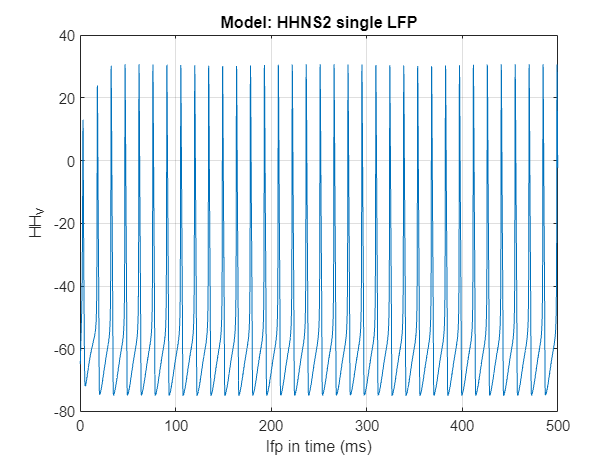

dl.dlPlotAllPotentials('lfp');

fprintf("Initial membrane potential = %f", dl.dlLastOutputs{1});

Initial membrane potential = 69.982504

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-1; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 10; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;
dlTrainOptions('dlTrainIncludeList') = ["HH_Iapp", "_Eleak"];
dlTrainOptions('dlTrainRestrictList') = ["HH_ileak_Eleak"];
dlTrainOptions('dlTrainRestrictCoef') = {.1};
dlTrainOptions('dlCheckpointCoefficient') = 2.0;
dlTrainOptions('dlUpdateVerbose') = 1;
dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> HH_Iapp
---> _Eleak
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> HH_ileak_Eleak
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->ExcludeDiverge was not determined in options map, default dlExcludeD

-->Log flag for loss plot is not specified; default = 1.


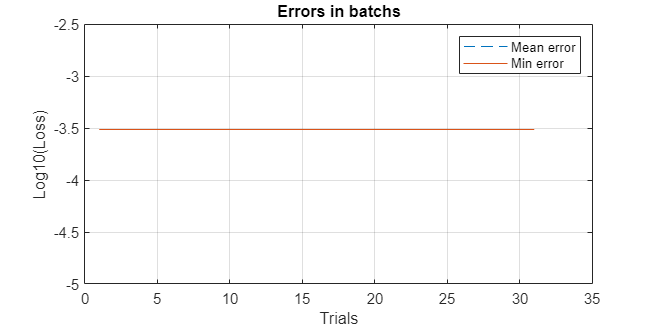


dl.dlPlotBatchErrors(1);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS2/Optimal 


dl.dlSimulate();

Total Memory Used <= 1 GB 
Done.


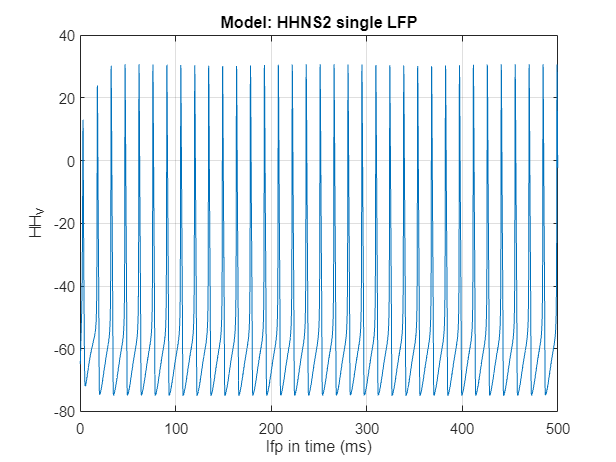

dl.dlPlotAllPotentials('lfp');

fprintf("Final aFR = %f", dl.dlLastOutputs{1});

Final aFR = 69.982504

optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final Iapp: %g, Eleak: %g\n', p.HH_Iapp, p.HH_ileak_Eleak);

Final Iapp: 9.50732, Eleak: -52.5016


## 2.1: Populatin baseline voltage optimization


$$:N \rightarrow f(r_v ; \nabla E_{leak})$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS3';

eqns={
  'dV/dt=Iapp+@current+noise*randn(1,N_pop); Iapp=0; noise=0'
};

Iapp = 10;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 5;
tauAMPA = 2;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 40};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 40};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS3', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.

PREPARING SOLVER:
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS3\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS3\solve\sim1\solve_ode_20230824135220_818.m
Compiling file: D:\Works\Computational\DynaSim\dlModels\HHNS3\solve\sim1\solve_ode_20230824135220_818.m
            to: D:\Works\Computational\DynaSim\dlModels\HHNS3\solve\sim1\solve_ode_20230824135220_818_mex
Code generation successful.

    MEX generation complete! 
    Elapsed time: 20.9 seconds. 
    Removing temporary codemex directory: D:\Works\Computational\DynaSim\dlModels\HHNS3\solve\sim1\c


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS3/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 3; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS3 
Params.mat file loaded from dlModels/HHNS3 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Initial TauD(IN): 5, ES_Noise = 40, INF_Noise = 40


target_FRQ = 70; % Hz
target_AV = -58; % mV

dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['ES', '_V'], 1:80, [10 RunDuration], 'av'}];
dlTargetParameters = {[{'MSE', 1, target_FRQ, 1}; {'MSE', 2, -58, 1}]}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-5; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.001, .001}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = [["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; ["ES_noise", "INfast_noise"]]; % Each array row will be overrided
                                  % by synchronizing to the first element
dlTrainOptions('dlCheckpointCoefficient') = 1.5;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

--->N.2:     "ES_noise"    "INfast_noise"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specifi

dl.dlSimulate();

Done.


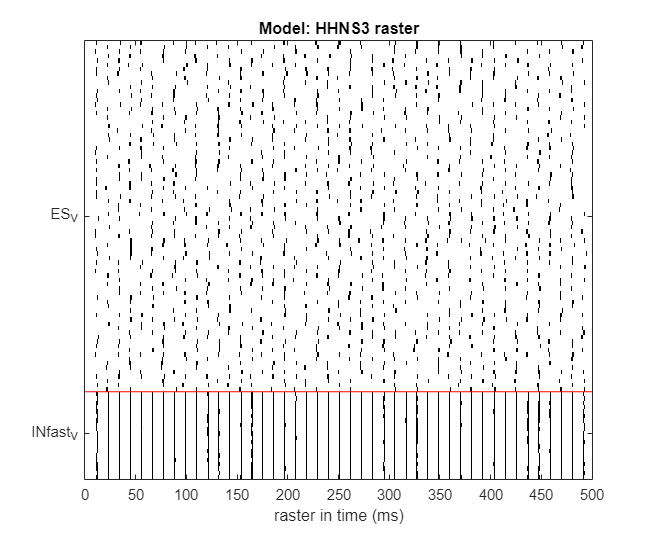

dl.dlPlotAllPotentials('raster');

fprintf("Initial firing rate = %f, membrane potential = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Initial firing rate = 34.100184, membrane potential = -64.083447


dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-2; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 20; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.2;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.001, .001}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = [["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; ["ES_noise", "INfast_noise"]]; % Each array row will be overrided
                                  % by synchronizing to the first element
dlTrainOptions('dlCheckpointCoefficient') = 1.4;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

--->N.2:     "ES_noise"    "INfast_noise"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if

-->Log flag for loss plot is not specified; default = 1.


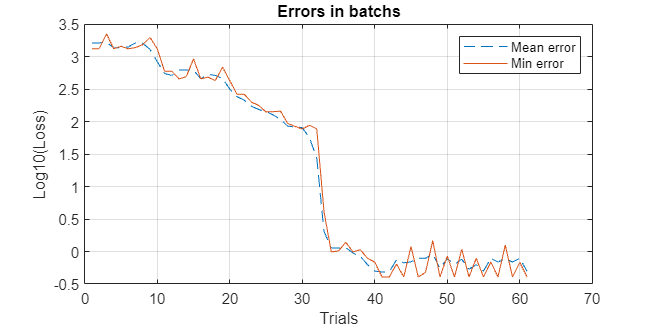


dl.dlPlotBatchErrors(1);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS3/Optimal 
---->Optimal [Parallel]


dl.dlSimulate();

Done.


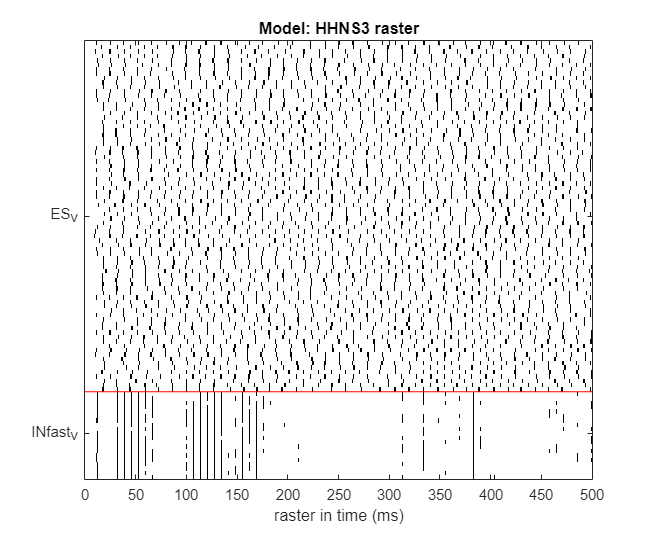

dl.dlPlotAllPotentials('raster');


fprintf("Final firing rate = %f, membrane potential = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Final firing rate = 69.424607, membrane potential = -57.727977


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Final TauD(IN): 0.922692, ES_Noise = 39.9991, INF_Noise = 39.9991


## 2.2: Populatin firing rate optimization


$$:N \rightarrow f(r_{fr} ; \nabla E_{leak}, I_{app})$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS4';

eqns={
  'dV/dt=Iapp+@current+noise*randn(1,N_pop); Iapp=0; noise=0'
};

Iapp = 10;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 5;
tauAMPA = 2;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 40};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 40};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS4', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:

PREPARING SOLVER:
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS4\solve\sim1
Saving params.mat


dl.dlSave();

## Load (ONLY IF ALREADY EXISTS)

id = 4; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS4 
Params.mat file loaded from dlModels/HHNS4 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Initial TauD(IN): 5, ES_Noise = 40, INF_Noise = 40


target_FRQ = 20; % Hz
target_FRQ2 = 70; % mV

dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'afr'}];
dlTargetParameters = {[{'MSE', 1, target_FRQ, 1}; {'MSE', 2, target_FRQ2, 1}]}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-5; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.001, .001}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = [["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; ["ES_noise", "INfast_noise"]]; % Each array row will be overrided
                                  % by synchronizing to the first element
dlTrainOptions('dlCheckpointCoefficient') = 1.5;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

--->N.2:     "ES_noise"    "INfast_noise"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specifi

dl.dlSimulate();

Done.


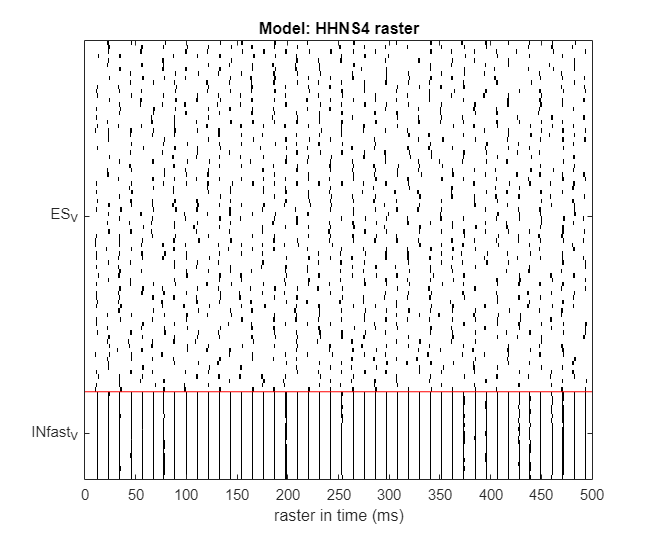

dl.dlPlotAllPotentials('raster');

fprintf("Initial firing rate ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Initial firing rate ES = 33.845134, INfast = 91.817996


dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-2; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 30; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.001, .001}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = [["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; ["ES_noise", "INfast_noise"]]; % Each array row will be overrided
                                  % by synchronizing to the first element
dlTrainOptions('dlCheckpointCoefficient') = 1.1;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

--->N.2:     "ES_noise"    "INfast_noise"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if

-->Log flag for loss plot is not specified; default = 1.


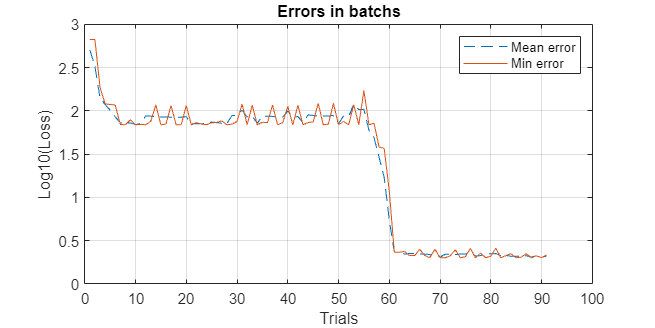


dl.dlPlotBatchErrors(1);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS4/Optimal 
---->Optimal [Parallel]


dl.dlSimulate();

Done.


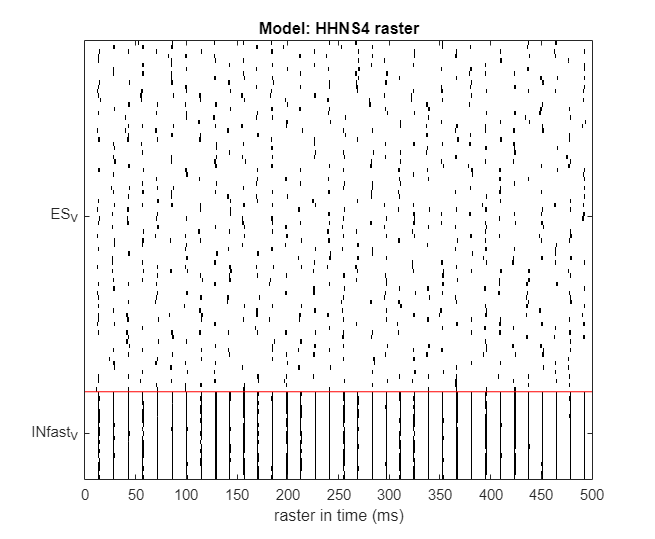

dl.dlPlotAllPotentials('raster');


fprintf("Final firing rate ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Final firing rate ES = 19.613344, INfast = 71.413997


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Final TauD(IN): 8.05073, ES_Noise = 40.0017, INF_Noise = 40.0017


## 2.3: Natural frequency optimization


$$:N \rightarrow f(<R,\omega_{Natural}>; \nabla I_{app}, Noise)$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS6';

eqns={
  'dV/dt=Iapp+@current+noise*randn(1,N_pop); Iapp=0; noise=0'
};

Iapp = 10;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 5;
tauAMPA = 2;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 40};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 40};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS6', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:


dl.dlSave();

## Load (ONLY IF ALREADY EXISTS)

id = 6; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS6 
Params.mat file loaded from dlModels/HHNS6 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Initial TauD(IN): 5, ES_Noise = 40, INF_Noise = 40


target_FRQ = 30; % Hz
target_FRQ2 = 30; % mV

dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'fnat'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'fnat'}];
dlTargetParameters = {[{'MSE', 1, target_FRQ, 1}; {'MSE', 2, target_FRQ2, 1}]}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-9; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.1;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (

dl.dlSimulate();

Done.



--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


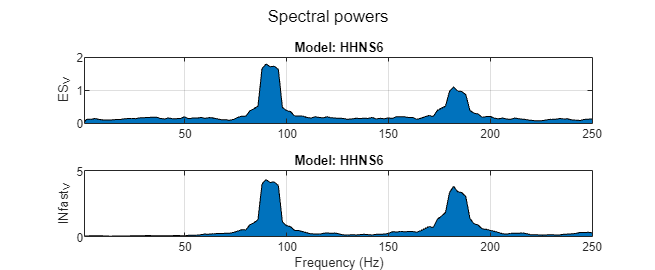

dl.dlPlotAllPotentials('avgfft');

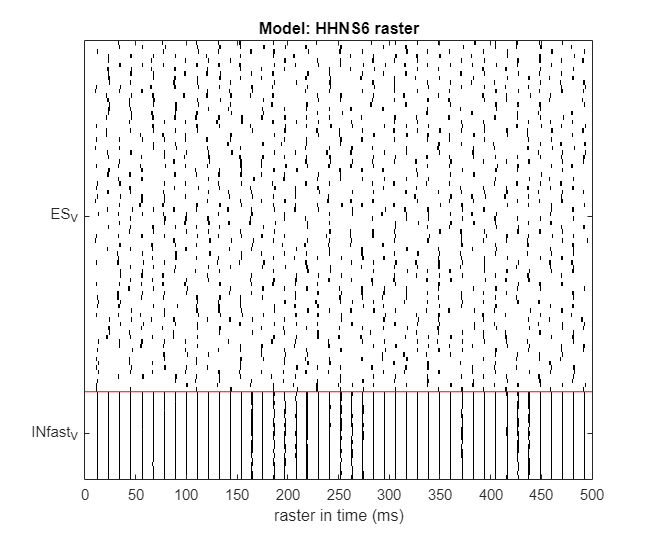

dl.dlPlotAllPotentials('raster');

fprintf("Initial natural frequency ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Initial natural frequency ES = 89.777596, INfast = 93.858396


dlTrainOptions = containers.Map(); % Train options; MUST be a Map() data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 10; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1; % Recommended to be 1 for debugging purposes
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {0.02, 0.02}; % Restrict rate coeffs (Variation restriction)
dlTrainOptions('dlTrainRestrictBound') = {[30 50], [30 50]}; % Restrict boundary values (PDE)
dlTrainOptions('dlCheckpointCoefficient') = 1.7;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (

-->Log flag for loss plot is not specified; default = 1.


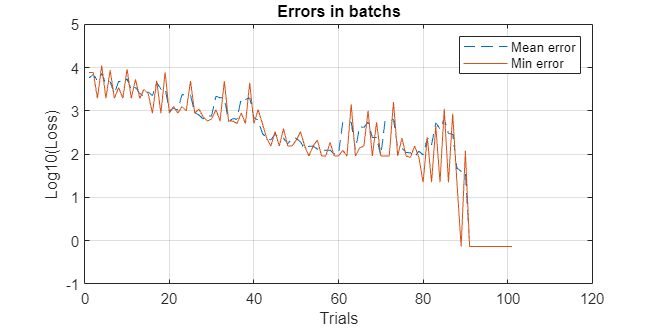

dl.dlPlotBatchErrors(1);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS6/Optimal 
---->Optimal [Parallel]


dl.dlSimulate();

Done.



--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


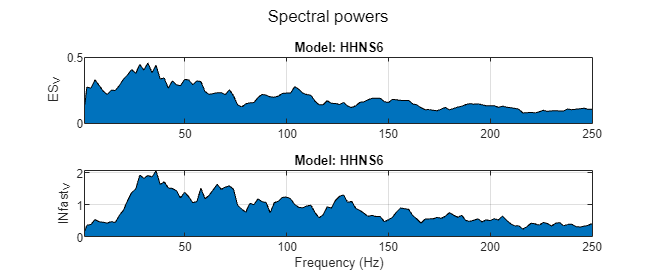

dl.dlPlotAllPotentials('avgfft');

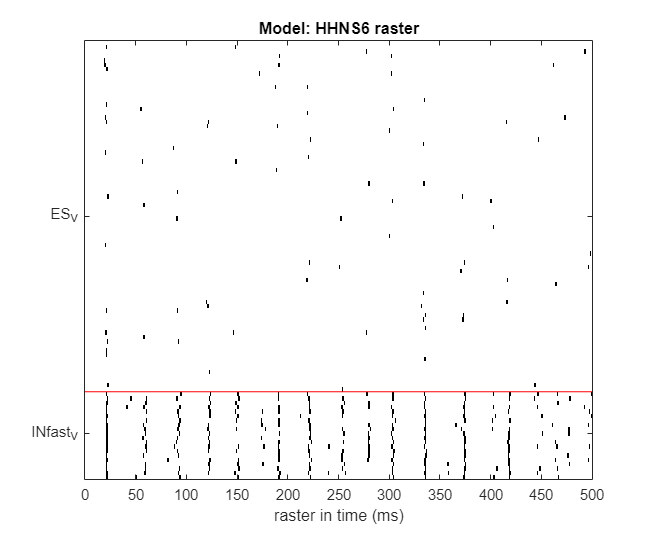

dl.dlPlotAllPotentials('raster');


fprintf("Final natural frequency ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Final natural frequency ES = 30.605999, INfast = 30.605999


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Final TauD(IN): 26.2092, ES_Noise = 40.1273, INF_Noise = 39.9595


## 2.4: Band frequency optimization


$$:N \rightarrow f(<R,\omega_{Natural}>; \nabla I_{app}, Noise)$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS7';

eqns={
  'dV/dt=Iapp+@current+noise*randn(1,N_pop); Iapp=0; noise=0'
};

Iapp = 10;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 5;
tauAMPA = 2;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 40};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 40};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS7', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:

PREPARING SOLVER:
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS7\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS7\solve\sim1\solve_ode_20230824152343_531.m
Compiling file: D:\Works\Computational\DynaSim\dlModels\HHNS7\solve\sim1\solve_ode_20230824152343_531.m
            to: D:\Works\Computational\DynaSim\dlModels\HHNS7\solve\sim1\solve_ode_20230824152343_531_mex
Code generation successful.

    MEX generation complete! 
    Elapsed time: 8.9 seconds. 
    Removing temporary codemex directory: D:\Works\Computational\DynaSim\dlModels\HHNS7\solve\sim1\codemex
Solve file solve_ode_20230824152343_531 does not yet exist in mex_dir D:\Works\Computational\DynaSim\dlMo


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS7/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 7; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS7 
Params.mat file loaded from dlModels/HHNS7 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

Initial TauD(IN): 5, ES_Noise = 40, INF_Noise = 40


target_FRQ = 25; % Hz
target_FRQ2 = 40; % Hz

dlInputParameters = {dlNullInputs(RunDuration)}; % Null inputs (no external stimulation).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'fnat'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'fnat'}];
dlTargetParameters = {[{'MSE', 1, target_FRQ, 1}; {'MSE', 2, target_FRQ2, 1}]}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-5; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element
dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:
-->dlBatchs (batch size) was not determined in options map, default dlBatchs = 1
--->Ignore dlBatchs if your update mode is trial or epoch.

-->Included variable(s) on fitting: 
---> ES_INfast_iGABAa_tauD
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->Update mode was not determined in options map, default dlUpdateMode = 'trial'
-->No custom logs specified; Ignore this if you did not have custom 

dl.dlSimulate();

Done.


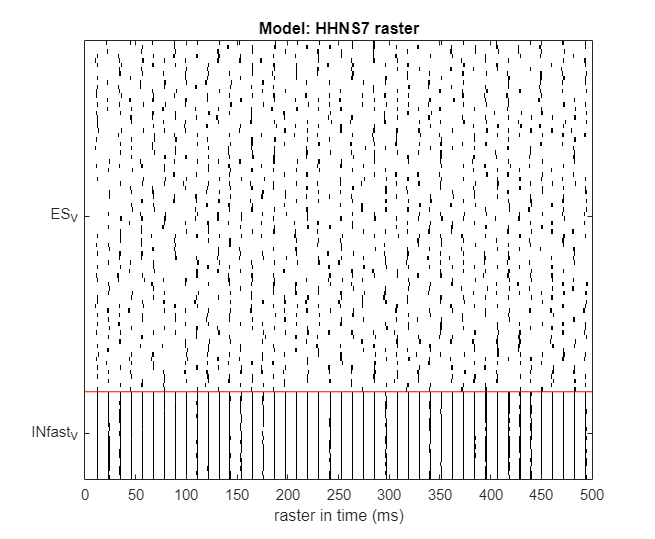

dl.dlPlotAllPotentials('raster');

fprintf("Initial natural frequency ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});

Initial natural frequency ES = 91.817996, INfast = 91.817996


dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-1; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 100; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_INfast_iGABAa_tauD", "ES_noise", "INfast_noise"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {0.05, 0.05}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element

dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

dl.dlPlotBatchErrors(1);
dl.dlLoadOptimal();
dl.dlSimulate();
dl.dlPlotAllPotentials('raster');

fprintf("Final natural frequency ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2});
optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

## 2.5: Band power spectrum ratio optimization


$$:N \rightarrow f(\frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}}; \nabla I_{app}, Noise)$$


RunDuration = 400; % In ms (miliseconds)
study_dir = 'dlModels/HHNS8';

eqns={
  'dV/dt=Icond+Iapp+@current+noise*randn(1,N_pop); Icond=0; Iapp=0; noise=0'
};

Iapp = 0;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 5;
tauAMPA = 2;

kIE = ones(20, 80)*0.5;
kEI = ones(80, 20)*0.5;
kII = ones(20, 20)*0.5;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 40};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 40};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIE};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA, 'netcon', kEI};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kII};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS8', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:

PREPARING SOLVER:
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS8\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS8\solve\sim1\solve_ode_20230824153231_152.m
Compiling file: D:\Works\Computational\DynaSim\dlModels\HHNS8\solve\sim1\solve_ode_20230824153231_152.m
            to: D:\Works\Computational\DynaSim\dlModels\HHNS8\solve\sim1\solve_ode_20230824153231_152_mex
Code generation successful.

    MEX generation complete! 
    Elapsed time: 9.1 seconds. 
    Removing temporary codemex directory: D:\Works\Computational\DynaSim\dlModels\HHNS8\solve\sim1\codemex
Solve file solve_ode_20230824153231_152 does not yet exist in mex_dir D:\Works\Computational\DynaSim\dlMo


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS8/dlFile.mat".


## Load (ONLY IF ALREADY EXISTS)

id = 8; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS8 
Params.mat file loaded from dlModels/HHNS8 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g, avg.IEconn = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise, mean(mean(p.INfast_ES_iAMPA_netcon)));

Initial TauD(IN): 5, ES_Noise = 40, INF_Noise = 40, avg.IEconn = 0.5


trialParams1 = containers.Map();
trialParams2 = containers.Map();

trialParams1('tspan') = [0 400];
trialParams2('tspan') = [0 400];
trialParams1('ES_Icond') = 10;
trialParams2('ES_Icond') = 0;

dlInputParameters = {trialParams1; trialParams2}; % Two inputs (Icond=0?10).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['ES', '_V'], 1:80, [10 RunDuration], 'av'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'av'}];
dlTargetParameters = {{{'QRPenalty', "ES_V", 0.85, 10., 10, 40, 40, 70}; {'MSE', 2, -60, .1}; {'MSE', 3, -55, .1}}; ...
    {{'QRPenalty', "ES_V", 1.15, 10., 10, 40, 40, 70}; {'MSE', 2, -60, .1}; {'MSE', 3, -55, .1}}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 0; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 2; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_noise", "INfast_noise"];

dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have c

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS8/Optimal 
---->Optimal [Parallel]


Condition1



	->Single trial running: 
Updating parameters of dlModels/HHNS8/solve > 
Done.

	-->Simulation outputs:     {[46.8149]}    {[-60.7980]}    {[-54.0259]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


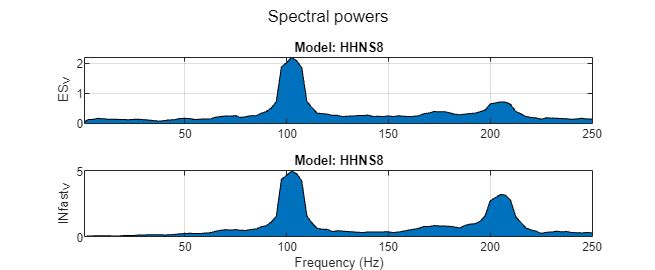

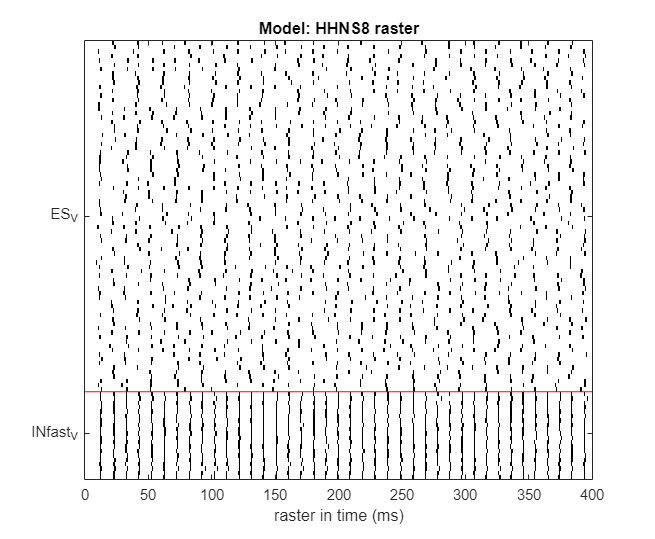

Condition2



	->Single trial running: 
Updating parameters of dlModels/HHNS8/solve > 
Done.

	-->Simulation outputs:     {[3.6209]}    {[-79.1774]}    {[-66.6737]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


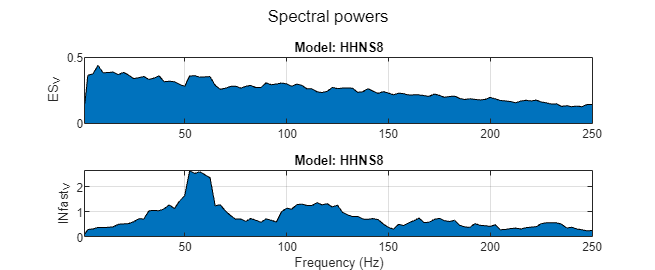

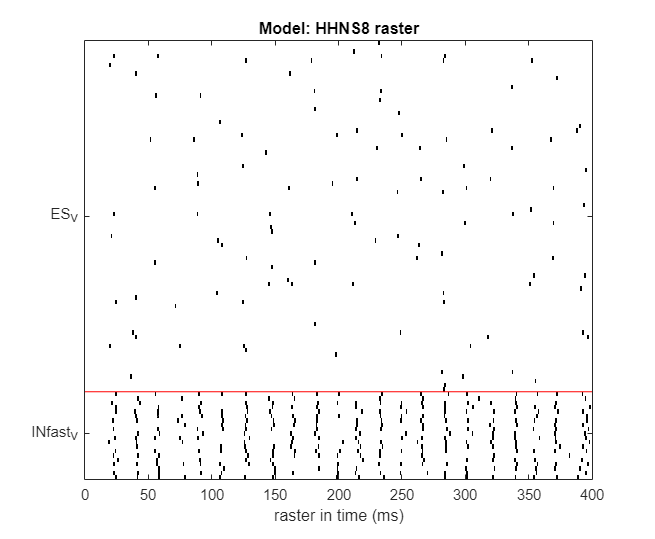

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end


fprintf("Initial aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

Initial aFR: 3.620866, AV: ES = -79.177406, INfast = -66.673695


% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-3; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 20; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_noise", "INfast_noise", "INfast_ES_iAMPA_netcon"];

dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[20 40], [20 40]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element

dlTrainOptions('dlCheckpointCoefficient') = 1.5;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_noise
---> INfast_noise
---> INfast_ES_iAMPA_netcon
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_noise
---> INfast_noise
-->Synchronized variable(s) on fitting: 
--->N.1:     "ES_INfast_iGABAa_tauD"    "INfast_INfast_iGABAa_tauD"

---->NOTE: SyncList format should be group(row)Xvariables(column).
---->On each group, All variables will be set to be equal to the first one.

-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model err

-->Log flag for loss plot is not specified; default = 1.


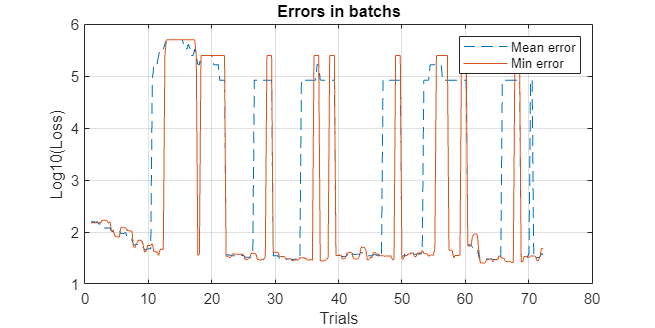

dl.dlPlotBatchErrors(4);

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS8/Optimal 
---->Optimal [Parallel]


Condition1



	->Single trial running: 
Updating parameters of dlModels/HHNS8/solve > 
Done.

	-->Simulation outputs:     {[46.8149]}    {[-60.7980]}    {[-54.0259]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


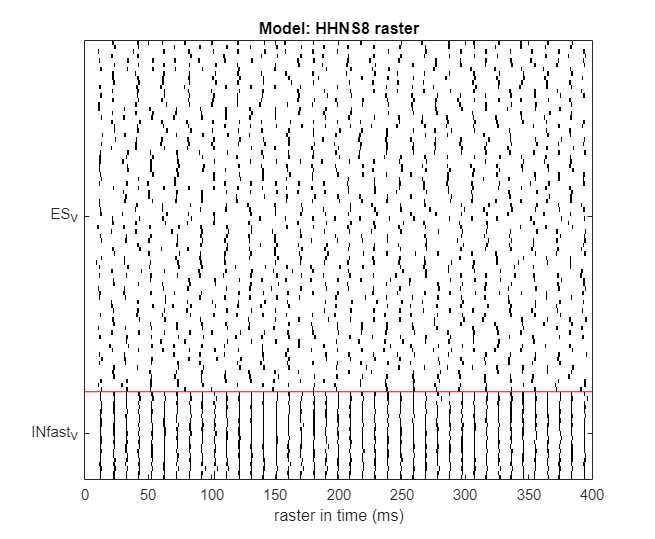

Condition2



	->Single trial running: 
Updating parameters of dlModels/HHNS8/solve > 
Done.

	-->Simulation outputs:     {[3.6209]}    {[-79.1774]}    {[-66.6737]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end

fprintf("Final aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

Final aFR: 3.620866, AV: ES = -79.177406, INfast = -66.673695


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, IN_Noise = %g, avg.IEconn = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise, mean(mean(p.INfast_ES_iAMPA_netcon)));

Final TauD(IN): 5, ES_Noise = 39.9976, IN_Noise = 39.9863, avg.IEconn = 0.490333


## 3.1: Single stimulus response optimization


$$:N?C_{p} \rightarrow f( [N] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}} < [C_{P}] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}}; \nabla I_{app}, Tau_D, Noise)$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS10'; 

eqns={
  'dV/dt=Icond+Iapp+@current+noise*randn(1,N_pop); Icond=0; Iapp=0; noise=0'
};

Iapp = 0;

gGABAfast = .1;
gAMPA = .1;

tauGABAfast = 15;
tauAMPA = 10;

kIE = ones(20, 80)*0.5;
kEI = ones(80, 20)*0.5;
kII = ones(20, 20)*0.5;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'Iapp',Iapp,'gNa',120,'gK',36,'noise', 30};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'Iapp',0,'gNa',120,'gK',36,'noise', 30};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIE};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA, 'netcon', kEI};

s.connections(3).direction='INfast->INfast';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kII};

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS10', 1); 
dl.dlSave();

## Load (ONLY IF ALREADY EXISTS)

id = 10; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial TauD(IN): %g, ES_Noise = %g, INF_Noise = %g, avg.IEconn = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise, mean(mean(p.INfast_ES_iAMPA_netcon)));
trialParams1 = containers.Map();
trialParams2 = containers.Map();
trialParams3 = containers.Map();

trialParams1('tspan') = [0 RunDuration];
trialParams2('tspan') = [0 RunDuration];
trialParams3('tspan') = [0 RunDuration];

trialParams1('ES_Icond') = 1;
trialParams2('ES_Icond') = 2;
trialParams3('ES_Icond') = 3;

freqPenalty = 1000.0;
dlInputParameters = {trialParams1; trialParams2; trialParams3}; % Two inputs (Icond=0?10).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['ES', '_V'], 1:80, [10 RunDuration], 'av'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'av'}];
dlTargetParameters = {{{'QRPenalty', "ES_V", 1.6, freqPenalty, 10, 40, 40, 100}; {'MSE', 2, -65, .01}; {'MSE', 3, -65, .01}}; ...
    {{'QRPenalty', "ES_V", 1.4, freqPenalty, 10, 40, 40, 100}; {'MSE', 2, -65, .01}; {'MSE', 3, -65, .01}}; ...
    {{'QRPenalty', "ES_V", 1.2, freqPenalty, 10, 40, 40, 100}; {'MSE', 2, -65, .01}; {'MSE', 3, -65, .01}}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-7; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_noise", "INfast_noise", "INfast_ES_iAMPA_netcon"];

dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[5 50], [5 50]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 3;
dlTrainOptions('dlTrainSyncList') = ["ES_INfast_iGABAa_tauD", ...
    "INfast_INfast_iGABAa_tauD"]; % Each array row will be overrided
                                  % by synchronizing to the first element

dlTrainOptions('dlCheckpointCoefficient') = 1.1;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-4; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 10; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 31;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_noise", "INfast_noise", "INfast_ES_iAMPA_netcon"];

dlTrainOptions('dlTrainRestrictList') = ["ES_noise", "INfast_noise"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {.1, .1}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[5 40], [5 40]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 3;
dlTrainOptions('dlUpdateMode') = 'batch';

dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);
dl.dlPlotBatchErrors(3);

dl.dlLoadOptimal();
for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end
fprintf("Final aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});
optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');
fprintf('Final TauD(IN): %g, ES_Noise = %g, INF_Noise = %g\n', p.ES_INfast_iGABAa_tauD, p.ES_noise, p.INfast_noise);

## 3.2: G/B conditions response optimization


$$:C_{p}?C_{U} \rightarrow f( [C_{U}] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}} <  [C_{P}] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}}; \nabla W_{context})$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS11';

eqns={
  'dV/dt=IappCue+wContext.*Context+@current+noise*randn(1,N_pop); Context=1; IappCue=0; wContext=0; noise=0'
};

IappCue = 10;
wContext = 0;

gGABAslow = .1;
gGABAfast = .1;
gAMPA = .1;

tauGABAslow = 20;
tauGABAfast = 5;
tauAMPA = 2;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'IappCue',IappCue,'gNa',120,'gK',36,'noise',40};
s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'IappCue',IappCue,'gNa',120,'gK',36,'noise',40};
s.populations(3).name='INslow';
s.populations(3).size=20;
s.populations(3).equations=eqns;
s.populations(3).mechanism_list={'iNa','iK'};
s.populations(3).parameters={'IappCue',0,'gNa',120,'gK',36,'noise',40};
s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};
s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};
s.connections(3).direction='INslow->ES';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow};
s.connections(4).direction='ES->INslow';
s.connections(4).mechanism_list={'iAMPA'};
s.connections(4).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};
s.connections(5).direction='INslow->INfast';
s.connections(5).mechanism_list={'iGABAa'};
s.connections(5).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow};
s.connections(6).direction='INslow->INslow';
s.connections(6).mechanism_list={'iGABAa'};
s.connections(6).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow};
s.connections(7).direction='INfast->INslow';
s.connections(7).mechanism_list={'iGABAa'};
s.connections(7).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};
s.connections(8).direction='INfast->INfast';
s.connections(8).mechanism_list={'iGABAa'};
s.connections(8).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

vary = {'INfast','IappCue',[0 IappCue]; 'INslow','wContext',[0 wContext/2 wContext]};

data = dsSimulate(s, 'tspan', [0 1000], 'downsample_factor', 10, ...
                     'solver', 'euler', 'dt', .002, ...
                     'compile_flag', 0, 'parallel_flag', 1, ...
                     'vary', vary, 'verbose_flag', 1);


PREPARING STUDY:
Creating study directory: D:\Works\Computational\DynaSim\study_20230825113227
Creating data directory: D:\Works\Computational\DynaSim\study_20230825113227\data
Creating results directory: D:\Works\Computational\DynaSim\study_20230825113227\results
saving study file: D:\Works\Computational\DynaSim\study_20230825113227\studyinfo.mat
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.

PREPARING SOLVER:

PREPARING SOLVER:

PREPARING SOLVER:

PREPARING SOLVER:

PREPARING SOLVER:

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\study_20230825113227\solve\sim4
Changing directory to D:\Works\Computational\DynaSim\study_20230825113227\solve\sim4
Saving params.mat
Creating solver directory D:\Works\Computational\DynaSim\study_20230825113227\solve\sim1
Changing directory to D:\Works\Computational\DynaSim\study_20230825113227\solve\sim1
Saving params.mat
Creating solver directory D:\Works\Compu


Parallel simulations complete.



dsPlot(data);

dsPlot(data, 'plot_type','raster');

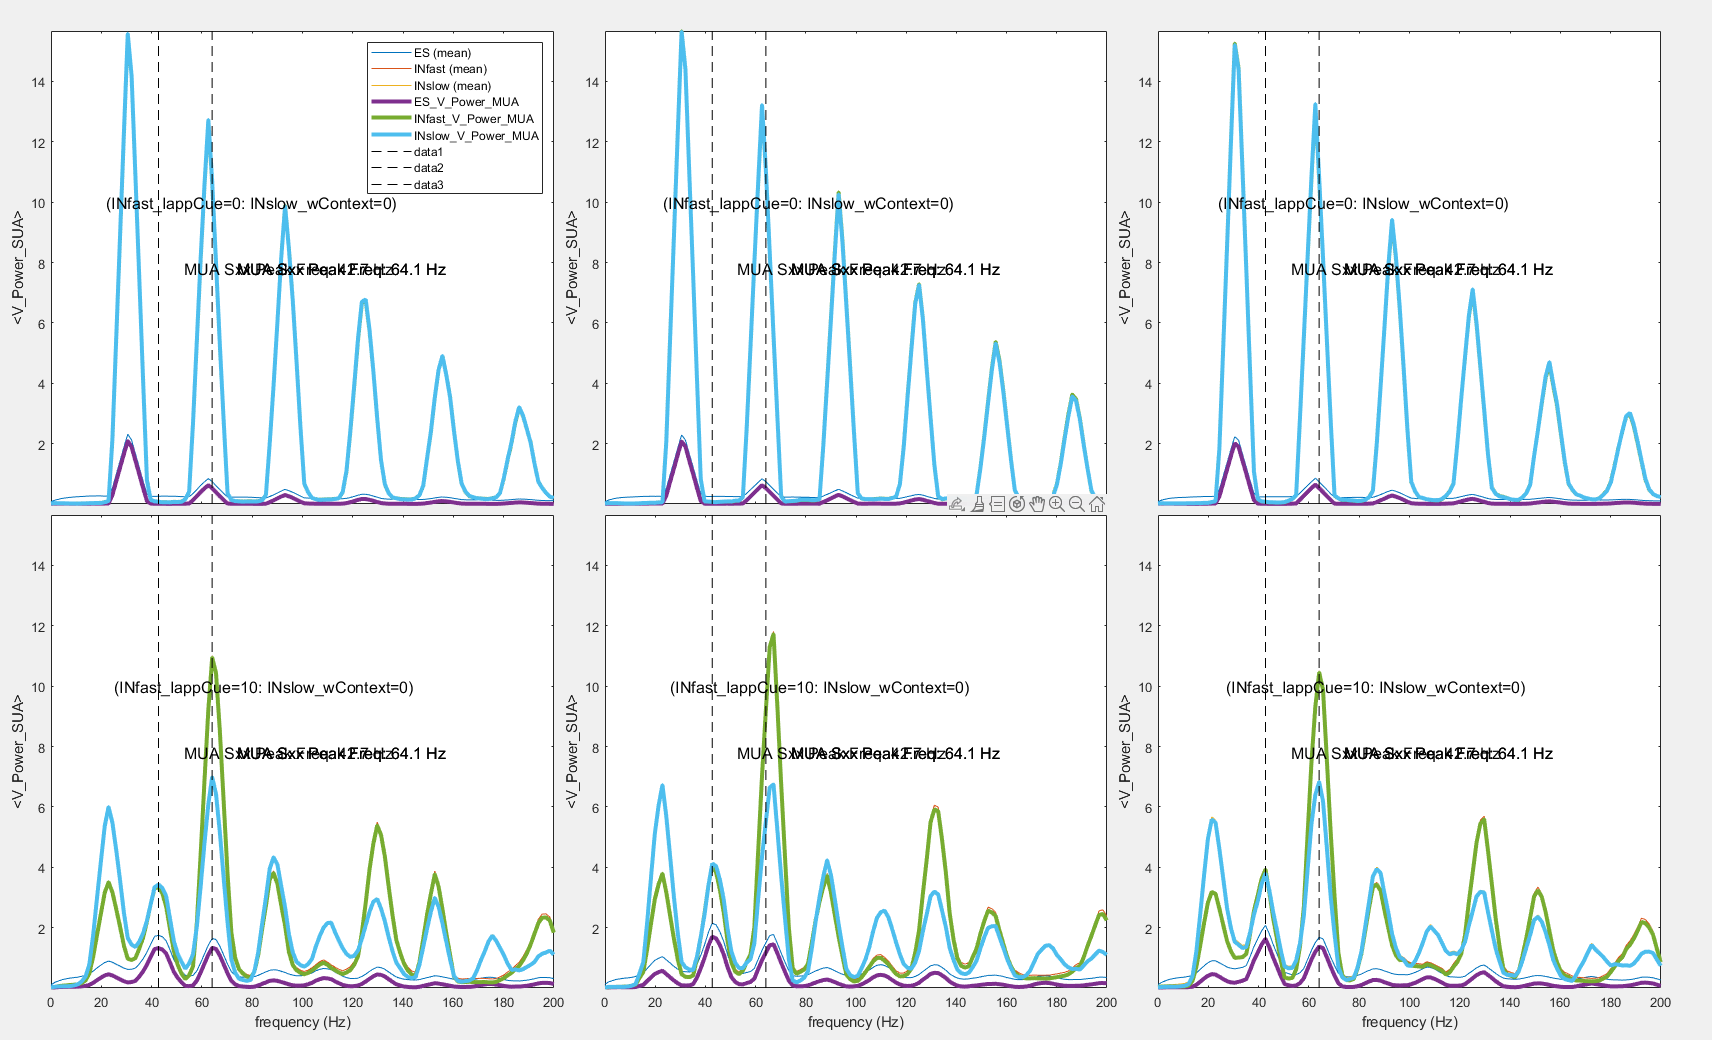

dsPlot(data, 'plot_type','power');

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS11', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: D:\Works\Computational\DynaSim\dlModels\HHNS11
Creating data directory: D:\Works\Computational\DynaSim\dlModels\HHNS11\data
Creating results directory: D:\Works\Computational\DynaSim\dlModels\HHNS11\results
saving study file: D:\Works\Computational\DynaSim\dlModels\HHNS11\studyinfo.mat

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\HHNS11\solve\sim1
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS11\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS11\solve\sim1\solve_ode_20230825113622_563.m
Compiling file: D:\Works\Computational\DynaSim\dlModels\HHNS11\solve\sim1\solve_ode_20230825113622_563.m
         


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS11/dlFile.mat".


## Loading DL object

id = 11; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS11 
Params.mat file loaded from dlModels/HHNS11 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial W(E): %g, W(INf) = %g, W(INs) = %g\n', p.ES_wContext, p.INfast_wContext, p.INslow_wContext);

Initial W(E): 0, W(INf) = 0, W(INs) = 0


trialParams1 = containers.Map();
trialParams2 = containers.Map();
trialParams3 = containers.Map();

trialParams1('tspan') = [0 RunDuration];
trialParams2('tspan') = [0 RunDuration];
% trialParams3('tspan') = [0 RunDuration];

trialParams1('ES_Context') = 0.1;
trialParams2('ES_Context') = 1;

trialParams1('INfast_Context') = 0.1;
trialParams2('INfast_Context') = 1;

trialParams1('INslow_Context') = 0.1;
trialParams2('INslow_Context') = 1;

freqPenalty = 1000.0;
dlInputParameters = {trialParams1; trialParams2}; % Two inputs (Icond=0?10).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['ES', '_V'], 1:80, [10 RunDuration], 'av'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'av'}];
dlTargetParameters = {{{'QRPenalty', "ES_V", .9, freqPenalty, 20, 40, 55, 75}; {'MSE', 2, -60, .1}; {'MSE', 3, -60, .1}}; ...
                      {{'QRPenalty', "ES_V", 1.8, freqPenalty, 20, 40, 55, 75}; {'MSE', 2, -60, .01}; {'MSE', 3, -60, .01}}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 0; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"];

dlTrainOptions('dlTrainRestrictList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {1., 1., 1.}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[-20 20], [-20 20], [-20 20]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have choosen adaptive lambda but forgot to determine a lambda cap. 

dl.dlSimulate();

Done.


Condition1



	->Single trial running: 
Updating parameters of dlModels/HHNS11/solve > 
Done.

	-->Simulation outputs:     {[6.2742]}    {[-70.4579]}    {[-63.1036]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


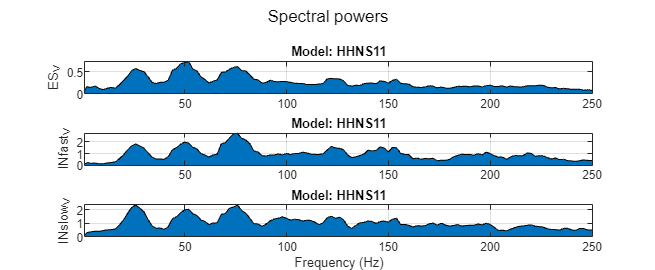

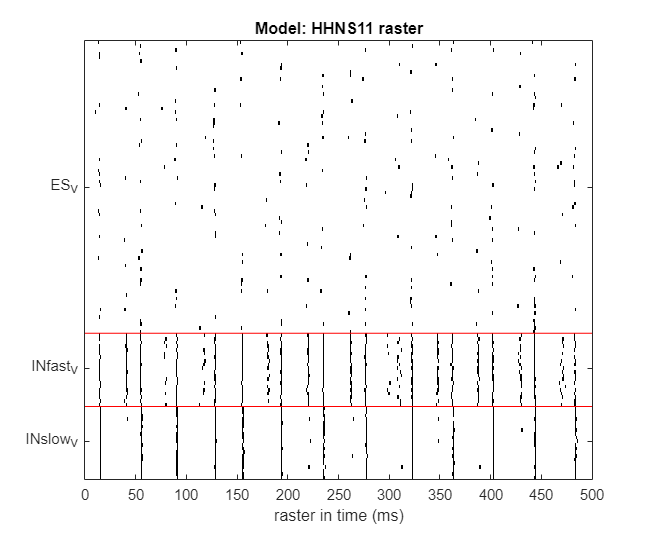

Condition2



	->Single trial running: 
Updating parameters of dlModels/HHNS11/solve > 
Done.

	-->Simulation outputs:     {[6.2742]}    {[-70.4579]}    {[-63.1036]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


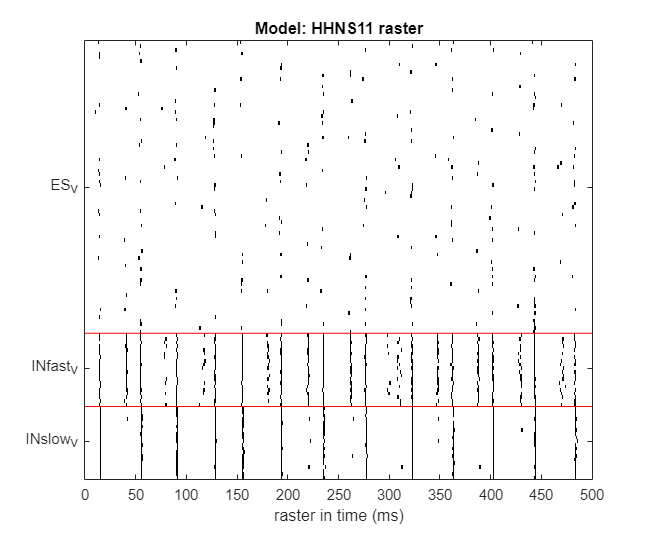

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end

fprintf("Initial aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

Initial aFR: 6.274230, AV: ES = -70.457910, INfast = -63.103615


dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-4; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 20; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"];

dlTrainOptions('dlTrainRestrictList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {1., 1., 1.}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[-10 20], [-10 20], [-10 20]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlCheckpointCoefficient') = 2.5;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have choosen adaptive lambda but forgot to determine a lambda cap. 

-->Log flag for loss plot is not specified; default = 1.


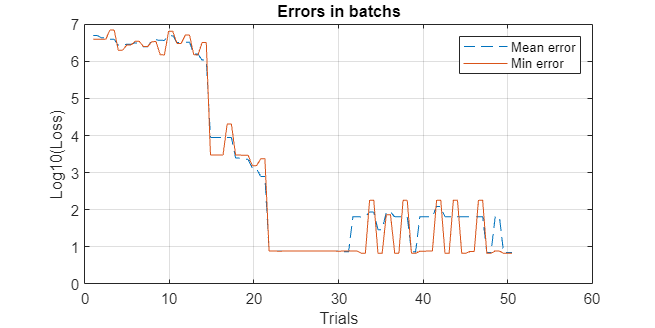

dl.dlPlotBatchErrors(dlTrainOptions('dlBatchs'));

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS11/Optimal 
---->Optimal [Parallel]


dl.dlSimulate();

Done.


Condition1



	->Single trial running: 
Updating parameters of dlModels/HHNS11/solve > 
Done.

	-->Simulation outputs:     {[6.1212]}    {[-70.4931]}    {[-62.8837]}



Temp edit for q subplots; average fft


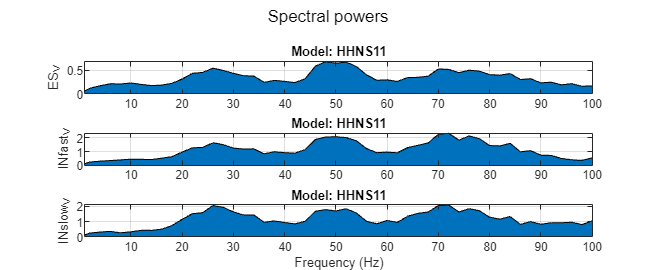

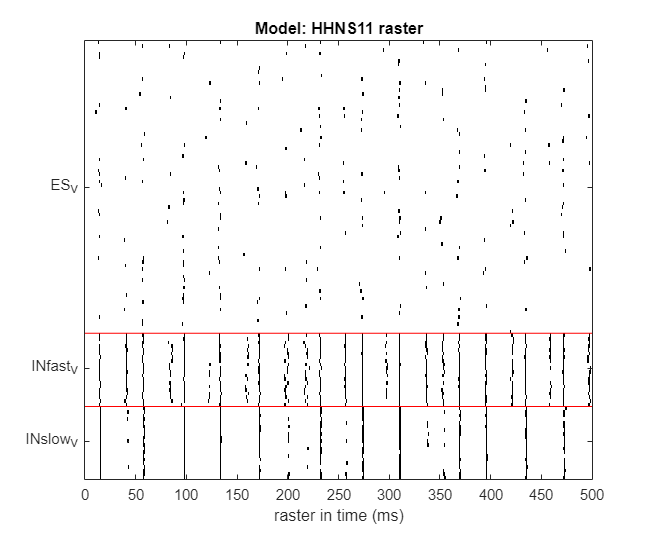

Condition2



	->Single trial running: 
Updating parameters of dlModels/HHNS11/solve > 
Done.

	-->Simulation outputs:     {[4.1063]}    {[-71.3375]}    {[-65.8565]}



Temp edit for q subplots; average fft


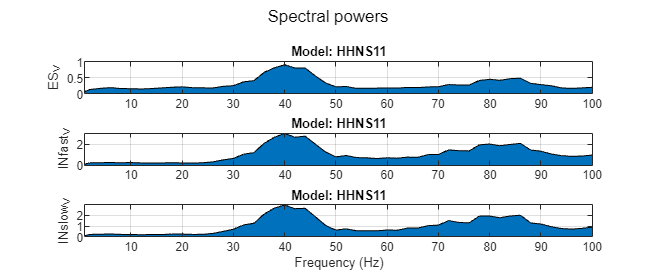

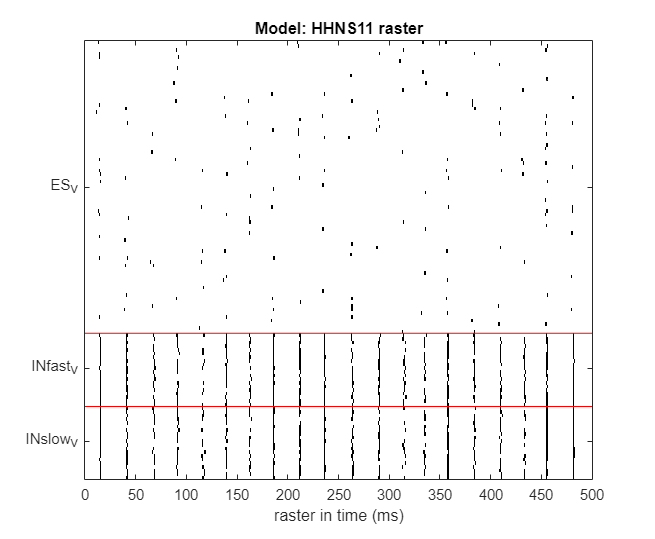

opts = containers.Map();
opts("lf") = 1;
opts("hf") = 100;

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft', opts);
    dl.dlPlotAllPotentials('raster');

end

fprintf("Final aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

Final aFR: 4.106305, AV: ES = -71.337481, INfast = -65.856476


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');fprintf('Final W(E): %g, W(INf) = %g, W(INs) = %g\n', p.ES_wContext, p.INfast_wContext, p.INslow_wContext);

Final W(E): -0.326673, W(INf) = -2.86079, W(INs) = 6.75982


## 3.2b: G/B conditions response optimization


$$:C_{p}?C_{U} \rightarrow f( [C_{U}] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}} <  [C_{P}] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}}; \nabla W_{context})$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS20';

eqns={
  'dV/dt=IappCue+wContext.*Context+@current+noise*randn(1,N_pop); Context=1; IappCue=0; wContext=0; noise=0'
};

IappCue = 10;
wContext = 0;

gGABAslow = .1;
gGABAfast = .1;
gAMPA = .1;

tauGABAslow = 50;
tauGABAfast = 12.5;
tauAMPA = 5;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'IappCue',IappCue,'gNa',120,'gK',36,'noise',40};
s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'IappCue',IappCue,'gNa',120,'gK',36,'noise',40};
s.populations(3).name='INslow';
s.populations(3).size=20;
s.populations(3).equations=eqns;
s.populations(3).mechanism_list={'iNa','iK'};
s.populations(3).parameters={'IappCue',0,'gNa',120,'gK',36,'noise',40};
s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};
s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};
s.connections(3).direction='INslow->ES';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow};
s.connections(4).direction='ES->INslow';
s.connections(4).mechanism_list={'iAMPA'};
s.connections(4).parameters={'tauD',tauAMPA,'gAMPA',gAMPA};
s.connections(5).direction='INslow->INfast';
s.connections(5).mechanism_list={'iGABAa'};
s.connections(5).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow};
s.connections(6).direction='INslow->INslow';
s.connections(6).mechanism_list={'iGABAa'};
s.connections(6).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow};
s.connections(7).direction='INfast->INslow';
s.connections(7).mechanism_list={'iGABAa'};
s.connections(7).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};
s.connections(8).direction='INfast->INfast';
s.connections(8).mechanism_list={'iGABAa'};
s.connections(8).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast};

vary = {'INfast','IappCue',[0 IappCue]; 'INslow','wContext',[0 wContext/2 wContext]};

data = dsSimulate(s, 'tspan', [0 1000], 'downsample_factor', 10, ...
                     'solver', 'euler', 'dt', .002, ...
                     'compile_flag', 0, 'parallel_flag', 1, ...
                     'vary', vary, 'verbose_flag', 1);


PREPARING STUDY:
Creating study directory: D:\Works\Computational\DynaSim\study_20230829164643
Creating data directory: D:\Works\Computational\DynaSim\study_20230829164643\data
Creating results directory: D:\Works\Computational\DynaSim\study_20230829164643\results
saving study file: D:\Works\Computational\DynaSim\study_20230829164643\studyinfo.mat
Starting parallel pool (parpool) using the 'Processes' profile ...
Connected to parallel pool with 12 workers.

PREPARING SOLVER:

PREPARING SOLVER:

PREPARING SOLVER:

PREPARING SOLVER:

PREPARING SOLVER:

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\study_20230829164643\solve\sim2
Changing directory to D:\Works\Computational\DynaSim\study_20230829164643\solve\sim2
Saving params.mat
Creating solver directory D:\Works\Computational\DynaSim\study_20230829164643\solve\sim5
Changing directory to D:\Works\Computational\DynaSim\study_20230829164643\solve\sim5
Saving params.mat
Creating solver directory D:\Works\Compu


Parallel simulations complete.



dsPlot(data);

dsPlot(data, 'plot_type','raster');

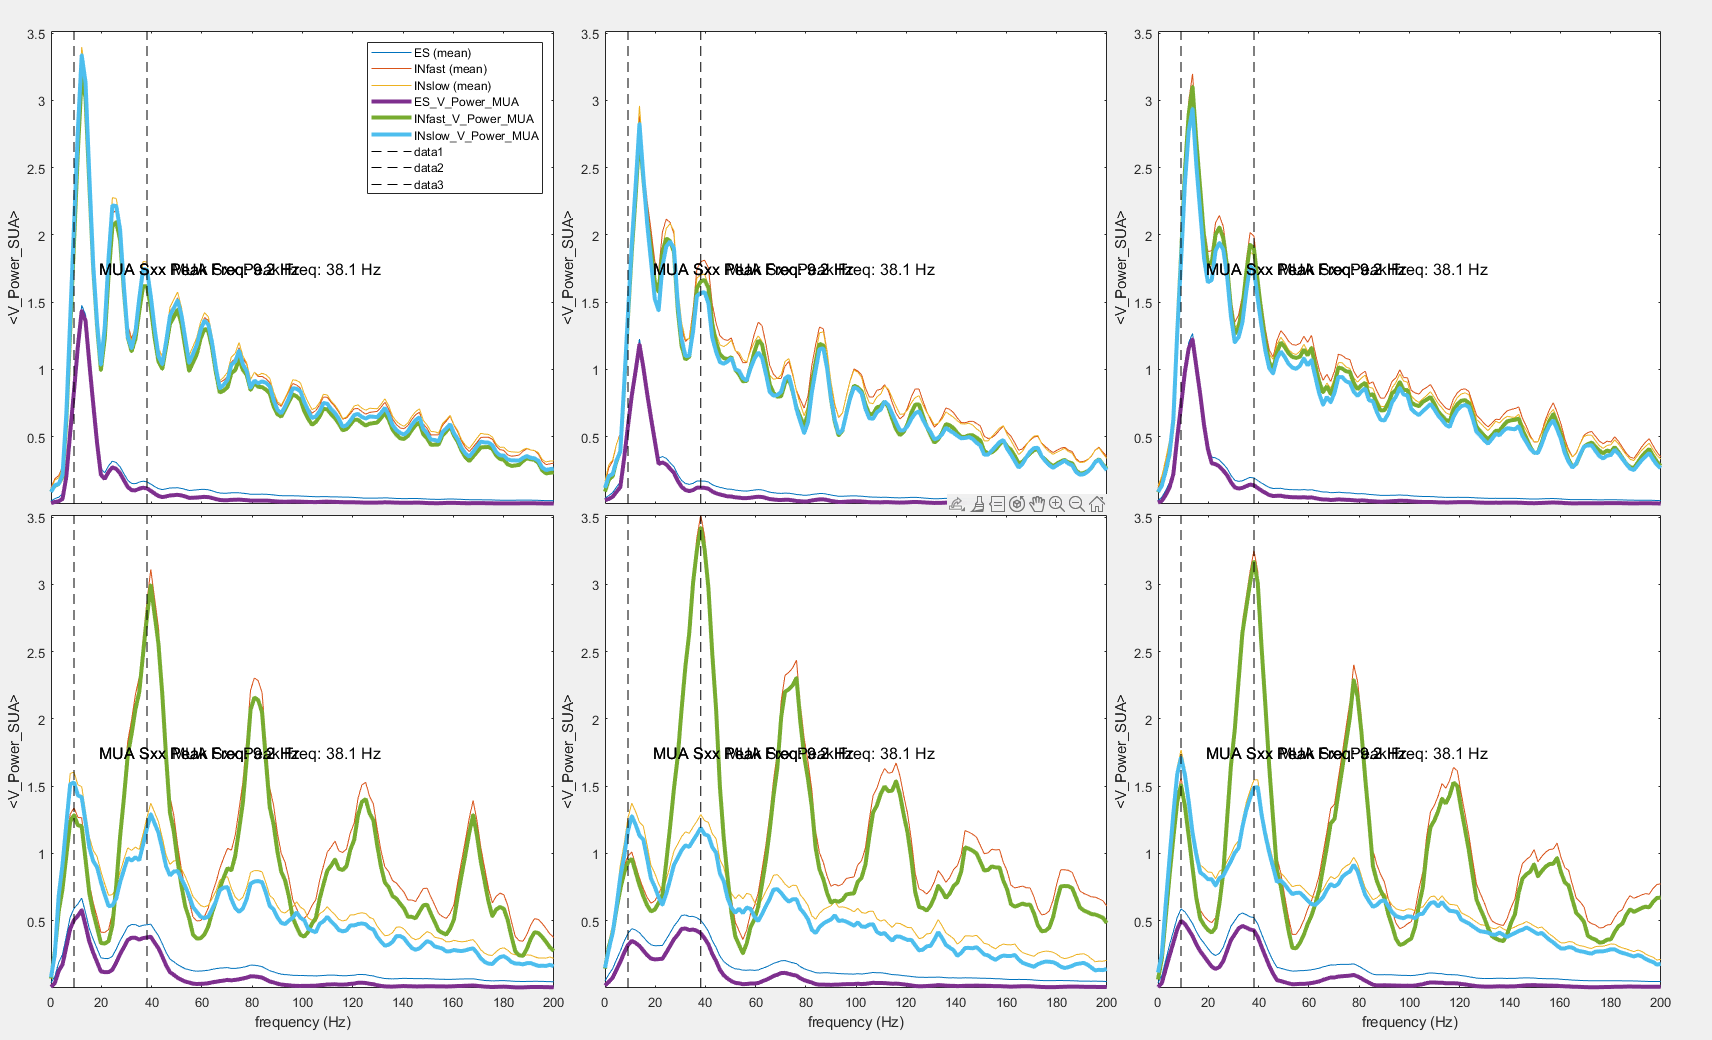

dsPlot(data, 'plot_type','power');

## Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS20', 1);



@DS.DL
>Creating DynaLearn model object 
->NOTE: Parallel flag is 0 by default.
-->To change parallel flag, set dlParallelFlag = 0 or 1
->Parallel flag is : 1

-->If you encountered an error related to parallel flag, set dlParallelFlag = 0.

PREPARING STUDY:
Creating study directory: D:\Works\Computational\DynaSim\dlModels\HHNS20
Creating data directory: D:\Works\Computational\DynaSim\dlModels\HHNS20\data
Creating results directory: D:\Works\Computational\DynaSim\dlModels\HHNS20\results
saving study file: D:\Works\Computational\DynaSim\dlModels\HHNS20\studyinfo.mat

PREPARING SOLVER:
Creating solver directory D:\Works\Computational\DynaSim\dlModels\HHNS20\solve\sim1
Changing directory to D:\Works\Computational\DynaSim\dlModels\HHNS20\solve\sim1
Saving params.mat
Creating solver file: D:\Works\Computational\DynaSim\dlModels\HHNS20\solve\sim1\solve_ode_20230829165155_751.m
Compiling file: D:\Works\Computational\DynaSim\dlModels\HHNS20\solve\sim1\solve_ode_20230829165155_751.m
         


Parallel simulations complete.

--------
--->Constructing graph ... Done.

@DS.DL:DynaLearn model created.


dl.dlSave();


->Model saved in "dlModels/HHNS20/dlFile.mat".


## Loading DL object

id = 20; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

DL object loaded from dlModels/HHNS20 
Params.mat file loaded from dlModels/HHNS20 
--------
--->Constructing graph ... Done.

Reinitialized.


param_file = fullfile(study_dir, 'params.mat');
load(param_file, 'p');
fprintf('Initial W(E): %g, W(INf) = %g, W(INs) = %g\n', p.ES_wContext, p.INfast_wContext, p.INslow_wContext);

Initial W(E): 0, W(INf) = 0, W(INs) = 0


trialParams1 = containers.Map();
trialParams2 = containers.Map();
trialParams3 = containers.Map();

trialParams1('tspan') = [0 RunDuration];
trialParams2('tspan') = [0 RunDuration];
% trialParams3('tspan') = [0 RunDuration];

trialParams1('ES_Context') = 0.1;
trialParams2('ES_Context') = 1;

trialParams1('INfast_Context') = 0.1;
trialParams2('INfast_Context') = 1;

trialParams1('INslow_Context') = 0.1;
trialParams2('INslow_Context') = 1;

freqPenalty = 100.0;
dlInputParameters = {trialParams1; trialParams2}; % Two inputs (Icond=0?10).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['ES', '_V'], 1:80, [10 RunDuration], 'av'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'av'}];
dlTargetParameters = {{{'QRPenalty', "ES_V", 1.0, freqPenalty, 10, 30, 45, 75}; {'MSE', 2, -60, .1}; {'MSE', 3, -60, .1}}; ...
                      {{'QRPenalty', "ES_V", 2.0, freqPenalty, 10, 30, 45, 75}; {'MSE', 2, -60, .01}; {'MSE', 3, -60, .01}}}; % Format: (1)Mode;(2)Output indices;(3)Target value;(4)Weight in loss equation

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 0; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"];

dlTrainOptions('dlTrainRestrictList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {1., 1., 1.}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[-20 20], [-20 20], [-20 20]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlCheckpointCoefficient') = 1.2;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have choosen adaptive lambda but forgot to determine a lambda cap. 

dl.dlSimulate();

Done.


Condition1



	->Single trial running: 
Updating parameters of dlModels/HHNS20/solve > 
Done.

	-->Simulation outputs:     {[1.9129]}    {[-71.0783]}    {[-65.3840]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


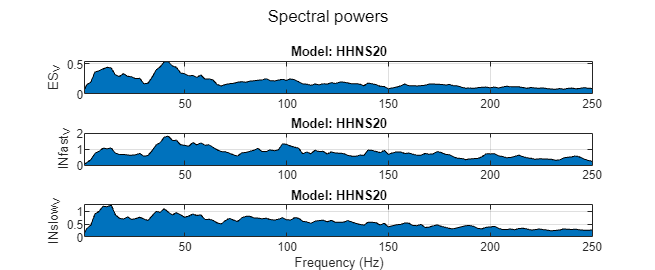

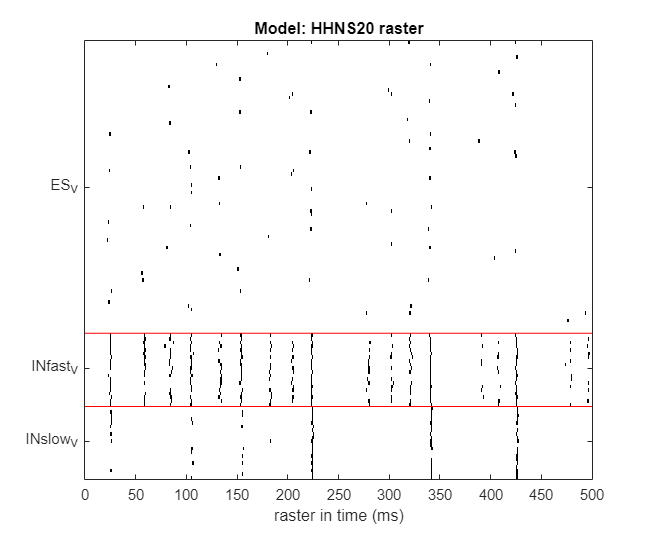

Condition2



	->Single trial running: 
Updating parameters of dlModels/HHNS20/solve > 
Done.

	-->Simulation outputs:     {[1.1732]}    {[-70.2075]}    {[-69.4134]}




--->No limit set or bad format:
---->opts map should have opts("lf") and opts("hf") as real positive values.

--->Default lf/hf = 1.0Hz/150.0HzTemp edit for q subplots; average fft


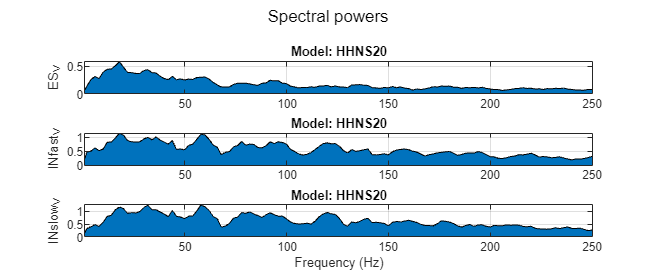

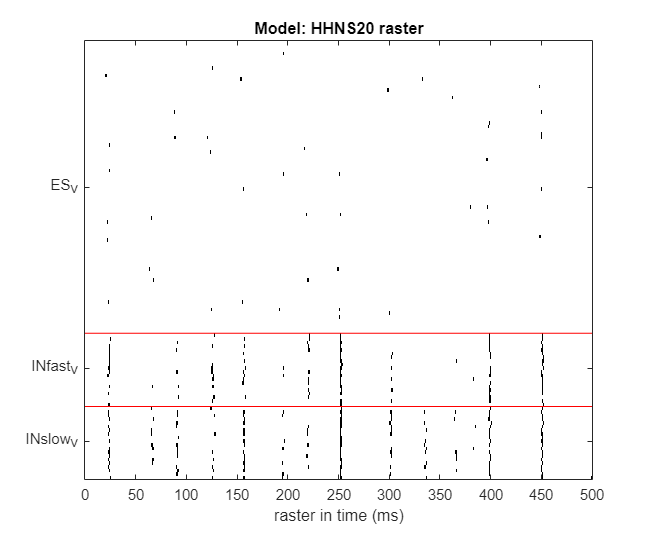

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end

fprintf("Initial aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

Initial aFR: 1.173230, AV: ES = -70.207543, INfast = -69.413358


dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-8; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 10; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"];

dlTrainOptions('dlTrainRestrictList') = ["ES_wContext", "INfast_wContext", "INslow_wContext"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {1., 1., 1.}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[-10 20], [-10 20], [-10 20]}; % Restrict boundary values (PDE)

dlTrainOptions('dlBatchs') = 2;
dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlCheckpointCoefficient') = 2.5;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

-> Training started:

-->Included variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Excluded variable(s) on fitting: 
-->No variables were manually excluded in the fitting exclude list.
--->No dynasim variables are excluded by default.
-->Restricted variable(s) on fitting: 
---> ES_wContext
---> INfast_wContext
---> INslow_wContext
-->Synchronized variable(s) on fitting: 
-->No variables were manually synchronized.
--->No dynasim variables are synchronized by default.
-->Learning rule was not determined in options map
--->Default dlLearningRule = 'GeneralizedStochasticDeltaRule'
-->No custom logs specified; Ignore this if you did not have custom logs.
-->Checkpoint flag was not determined in options map, default dlCheckpoint = 'true'
-->dlUpdateVerbose is 1 (On)
-->Adaptive lambda is active. Lambda (learning rate) will be changed based on volatility of model error.
--->Reminder: you have choosen adaptive lambda but forgot to determine a lambda cap. 

-->Log flag for loss plot is not specified; default = 1.


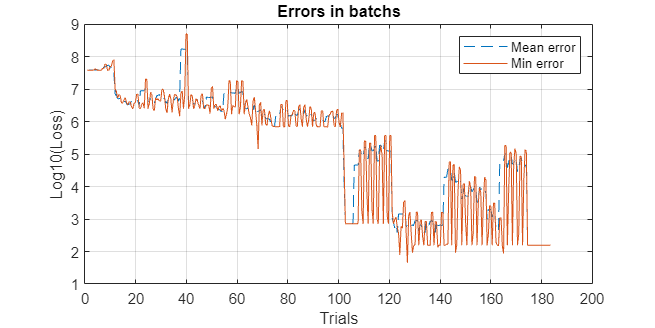

dl.dlPlotBatchErrors(dlTrainOptions('dlBatchs'));

dl.dlLoadOptimal();

		Checkpoint file loaded from dlModels/HHNS20/Optimal 
---->Optimal [Parallel]


dl.dlSimulate();

Done.


Condition1



	->Single trial running: 
Updating parameters of dlModels/HHNS20/solve > 
Done.

	-->Simulation outputs:     {[1.9384]}    {[-71.0008]}    {[-65.1954]}



Temp edit for q subplots; average fft


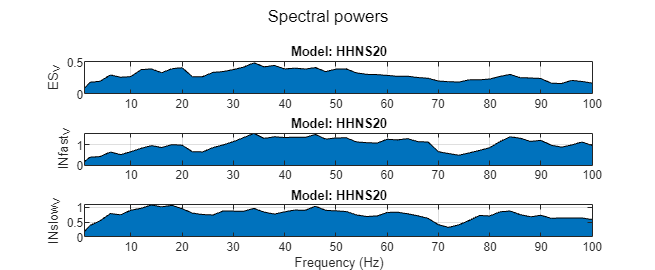

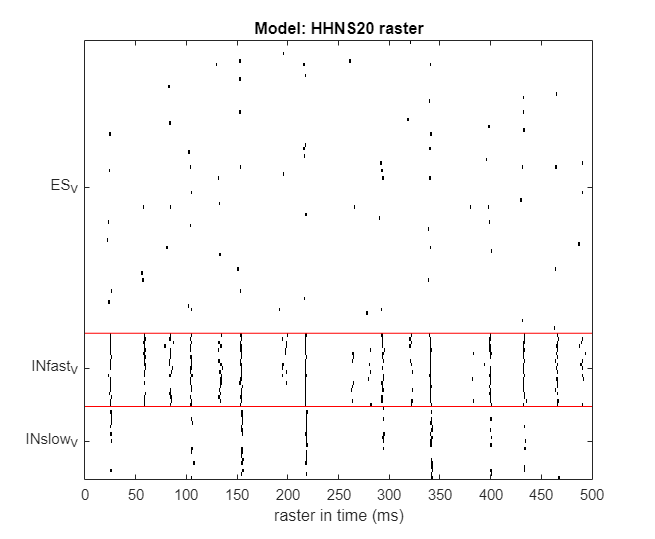

Condition2



	->Single trial running: 
Updating parameters of dlModels/HHNS20/solve > 
Done.

	-->Simulation outputs:     {[1.3008]}    {[-70.1965]}    {[-69.2048]}



Temp edit for q subplots; average fft


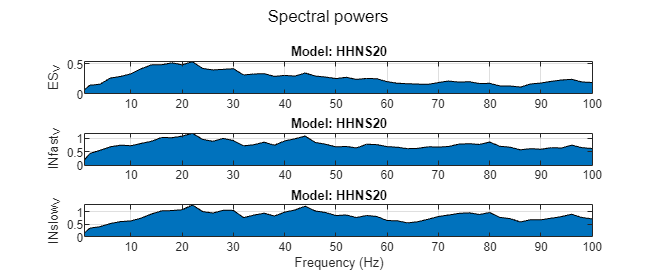

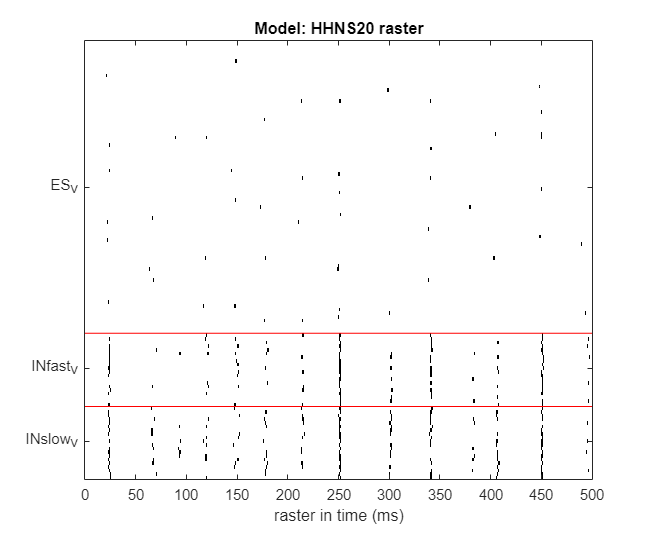

opts = containers.Map();
opts("lf") = 1;
opts("hf") = 100;

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft', opts);
    dl.dlPlotAllPotentials('raster');

end

fprintf("Final aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

Final aFR: 1.300755, AV: ES = -70.196520, INfast = -69.204801


optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');fprintf('Final W(E): %g, W(INf) = %g, W(INs) = %g\n', p.ES_wContext, p.INfast_wContext, p.INslow_wContext);

Final W(E): 2.41618, W(INf) = -1.6308, W(INs) = 10.6797


## 3.3: Transition on single to multiple response optimization


$$:C_{i}?C_{p} \rightarrow f( [N] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}} < [C_{P};C_{i}] \frac{\beta_{8-30Hz}}{\gamma_{40-90Hz}}; \nabla I_{app}, Tau_D, Noise)$$


RunDuration = 500; % In ms (miliseconds)
study_dir = 'dlModels/HHNS13';

eqns={
  'dV/dt=IappCue*(t > 0 & t < 250)+Context*(t > 0 & t < 500)+@current+noise*randn(1,N_pop); Context=1; IappCue=0; noise=0'
};

IappCue = 10;

gGABAslow = .1;
gGABAfast = .1;
gAMPA = .1;

tauGABAslow = 20;
tauGABAfast = 5;
tauAMPA = 2;

kIE = ones(20, 80)*0.5;
kEI = ones(80, 20)*0.5;
kII = ones(20, 20)*0.5;

s=[];
s.populations(1).name='ES';
s.populations(1).size=80;
s.populations(1).equations=eqns;
s.populations(1).mechanism_list={'iNa','iK'};
s.populations(1).parameters={'IappCue',IappCue,'gNa',120,'gK',36,'noise',40};

s.populations(2).name='INfast';
s.populations(2).size=20;
s.populations(2).equations=eqns;
s.populations(2).mechanism_list={'iNa','iK'};
s.populations(2).parameters={'IappCue',IappCue,'gNa',120,'gK',36,'noise',40};

s.populations(3).name='INslow';
s.populations(3).size=20;
s.populations(3).equations=eqns;
s.populations(3).mechanism_list={'iNa','iK'};
s.populations(3).parameters={'IappCue',0,'gNa',120,'gK',36,'noise',40};

s.connections(1).direction='INfast->ES';
s.connections(1).mechanism_list={'iGABAa'};
s.connections(1).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kIE};

s.connections(2).direction='ES->INfast';
s.connections(2).mechanism_list={'iAMPA'};
s.connections(2).parameters={'tauD',tauAMPA,'gAMPA',gAMPA, 'netcon', kEI};

s.connections(3).direction='INslow->ES';
s.connections(3).mechanism_list={'iGABAa'};
s.connections(3).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kIE};

s.connections(4).direction='ES->INslow';
s.connections(4).mechanism_list={'iAMPA'};
s.connections(4).parameters={'tauD',tauAMPA,'gAMPA',gAMPA, 'netcon', kEI};

s.connections(5).direction='INslow->INfast';
s.connections(5).mechanism_list={'iGABAa'};
s.connections(5).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kII};

s.connections(6).direction='INslow->INslow';
s.connections(6).mechanism_list={'iGABAa'};
s.connections(6).parameters={'tauD',tauGABAslow,'gGABAa',gGABAslow, 'netcon', kII};

s.connections(7).direction='INfast->INslow';
s.connections(7).mechanism_list={'iGABAa'};
s.connections(7).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kII};

s.connections(8).direction='INfast->INfast';
s.connections(8).mechanism_list={'iGABAa'};
s.connections(8).parameters={'tauD',tauGABAfast,'gGABAa',gGABAfast, 'netcon', kII};

vary = {'INfast','IappCue',[0 IappCue]};% 'INslow','wContext',[0 wContext/2 wContext]};

data = dsSimulate(s, 'tspan', [0 500], 'downsample_factor', 10, ...
                     'solver', 'euler', 'dt', .01, ...
                     'compile_flag', 0, 'parallel_flag', 1, ...
                     'vary', vary, 'verbose_flag', 1);
dsPlot(data);
dsPlot(data, 'plot_type','raster');
dsPlot(data, 'plot_type','power');

## 3.3: Passing to DynaLearn

dl = DynaLearn(s, study_dir, 'mex', 'HHNS13', 1);
dl.dlSave();

## 3.3: Loading

id = 13; % 1, 2, ...
dl = DynaLearn.dlLoader(char("dlModels/HHNS" + num2str(id)));

% param_file = fullfile(study_dir, 'params.mat');
% load(param_file, 'p');
% fprintf('Initial W(E): %g, W(INf) = %g, W(INs) = %g\n', p.ES_wContext, p.INfast_wContext, p.INslow_wContext);
trialParams1 = containers.Map();
trialParams2 = containers.Map();
trialParams3 = containers.Map();
trialParams4 = containers.Map();

trialParams1('tspan') = [0 RunDuration];
trialParams2('tspan') = [0 RunDuration];
trialParams3('tspan') = [0 RunDuration];
trialParams4('tspan') = [0 RunDuration];

trialParams1('ES_Context') = 0;
trialParams2('ES_Context') = 0;
trialParams3('ES_Context') = 0;
trialParams4('ES_Context') = 0;

trialParams1('ES_IappCue') = 0;
trialParams2('ES_IappCue') = 10;
trialParams3('ES_IappCue') = 0;
trialParams4('ES_IappCue') = 10;

trialParams1('INfast_Context') = 0;
trialParams2('INfast_Context') = 0;
trialParams3('INfast_Context') = 0;
trialParams4('INfast_Context') = 0;

trialParams1('INfast_IappCue') = 0;
trialParams2('INfast_IappCue') = 0;
trialParams3('INfast_IappCue') = 0;
trialParams4('INfast_IappCue') = 0;

trialParams1('INslow_Context') = 0;
trialParams2('INslow_Context') = 0;
trialParams3('INslow_Context') = 10;
trialParams4('INslow_Context') = 10;

trialParams1('INslow_IappCue') = 0;
trialParams2('INslow_IappCue') = 0;
trialParams3('INslow_IappCue') = 0;
trialParams4('INslow_IappCue') = 0;

freqPenalty = 10.0;
dlInputParameters = {trialParams1; trialParams2; trialParams3; trialParams4}; % Two inputs (Icond=0?10).
dlOutputParameters = [{['ES', '_V'], 1:80, [10 RunDuration], 'afr'}; {['ES', '_V'], 1:80, [10 RunDuration], 'av'}; {['INfast', '_V'], 1:20, [10 RunDuration], 'av'}];
dlTargetParameters = {{{'QRPenalty', "ES_V", 1.0, freqPenalty, 15, 30, 40, 90}; {'MSE', 2, -60, .001}; {'MSE', 3, -60, .001}}; ...
                      {{'QRPenalty', "ES_V", 0.9, freqPenalty, 15, 30, 40, 90}; {'MSE', 2, -60, .001}; {'MSE', 3, -60, .001}}; ...
                      {{'QRPenalty', "ES_V", 1.1, freqPenalty, 15, 30, 40, 90}; {'MSE', 2, -60, .001}; {'MSE', 3, -60, .001}}; ...
                      {{'QRPenalty', "ES_V", 1.2, freqPenalty, 15, 30, 40, 90}; {'MSE', 2, -60, .001}; {'MSE', 3, -60, .001}}};

% Define training options
dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 0; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 1; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.4;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 11;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["_netcon", "INslow_INslow_iGABAa_tauD", "INfast_INfast_iGABAa_tauD"];

dlTrainOptions('dlTrainRestrictList') = ["INslow_INslow_iGABAa_tauD", "INfast_INfast_iGABAa_tauD"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {1., 1.}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[10 40], [2 15]}; % Restrict boundary values (PDE)
dlTrainOptions('dlTrainSyncList') = [["INslow_INslow_iGABAa_tauD", ...
    "ES_INslow_iGABAa_tauD"]; ["INfast_INfast_iGABAa_tauD", ...
    "ES_INfast_iGABAa_tauD"]];

dlTrainOptions('dlBatchs') = 4;
dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlCheckpointCoefficient') = 100;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);

dl.dlSimulate();
for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft');
    dl.dlPlotAllPotentials('raster');

end
fprintf("Initial aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});

dlTrainOptions = containers.Map(); % Train options; MUST be a map data structure
dlTrainOptions('dlLambda') = 1e-5; % Fitting/Learning rate
dlTrainOptions('dlEpochs') = 20; % Total iterations 
dlTrainOptions('dlEnhancedMomentum') = 0.0;

dlTrainOptions('dlExcludeDiverge') = 0; % Exclude non-optimals from model log
dlTrainOptions('dlCheckpointLengthCap') = 41;
dlTrainOptions('dlUpdateVerbose') = 1;
dlTrainOptions('dlTrainIncludeList') = ["_netcon", "INslow_INslow_iGABAa_tauD", "INfast_INfast_iGABAa_tauD"];

dlTrainOptions('dlTrainRestrictList') = ["INslow_INslow_iGABAa_tauD", "INfast_INfast_iGABAa_tauD"]; % Restrict list
dlTrainOptions('dlTrainRestrictCoef') = {1., 1.}; % Restrict coeffs
dlTrainOptions('dlTrainRestrictBound') = {[10 40], [2 15]}; % Restrict boundary values (PDE)
dlTrainOptions('dlTrainSyncList') = [["INslow_INslow_iGABAa_tauD", ...
    "ES_INslow_iGABAa_tauD"]; ["INfast_INfast_iGABAa_tauD", ...
    "ES_INfast_iGABAa_tauD"]];

dlTrainOptions('dlBatchs') = 4;
dlTrainOptions('dlUpdateMode') = 'batch';
dlTrainOptions('dlCheckpointCoefficient') = 1.5;

dl.dlTrain(dlInputParameters, dlOutputParameters, dlTargetParameters, dlTrainOptions);
dl.dlPlotBatchErrors(dlTrainOptions('dlBatchs'));

dl.dlLoadOptimal();
dl.dlSimulate();
opts = containers.Map();
opts("lf") = 1;
opts("hf") = 100; 

for i = 1:max(size(dlInputParameters, 1))

    disp("Condition" + num2str(i));
    dl.dlRunSimulation(dlInputParameters{i}, dlOutputParameters);
    dl.dlPlotAllPotentials('avgfft', opts);
    dl.dlPlotAllPotentials('raster');

end
fprintf("Final aFR: %f, AV: ES = %f, INfast = %f\n", dl.dlLastOutputs{1}, dl.dlLastOutputs{2}, dl.dlLastOutputs{3});
optimal_param_file = fullfile(study_dir, 'Optimalparams.mat');
load(optimal_param_file, 'p');fprintf('Final W(E): %g, W(INf) = %g, W(INs) = %g\n', p.ES_wContext, p.INfast_wContext, p.INslow_wContext);

## END